# EE451 Homework 4 

# Lisa Jacklin

# 9/28/2023

## Problem 5

### A. Please see twosidedfft.m file which is included in text form below, and is uploaded as a .m file as well.

% function Xa = twosidedfft(x, fs, freq)
%     % x: Input discrete signal
%     % fs: Sampling frequency in Hz
%     % freq: Vector of frequencies (Hz) at which you want to evaluate the Fourier transform
%     % Xa: Complex Fourier transform values at the specified frequencies
%     
%     N = length(x); % Length of the input signal
%     t = (0:N-1) / fs; % Time vector
%     Xa = zeros(size(freq)); % Initialize output
% 
%     for k = 1:length(freq)
%         f = freq(k);
%         Xa(k) = sum(x .* exp(-1j * 2 * pi * f * t));
%     end
% end

### B.

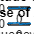

% Define your input signal x(n) and sampling frequency fs
fs = 100; % Example sampling frequency of 100Hz
N = 128;
t = 0:N-1; % Time vector from 0 to 1 second
x = cos(2 * pi * 30 * t); % Example input signal

% Define the frequencies at which to calculate the Fourier transform
freq = -50:1:50; % Example frequency vector from -50 Hz to 50 Hz

% Call the function to calculate the Fourier transform
Xa = twosidedfft(x, fs, freq);

% Plot the magnitude and phase of the Fourier transform
figure;
subplot(2,1,1);
plot(freq, abs(Xa));
title('Magnitude of Xa(f)');
xlabel('Frequency (Hz)'); ylabel('|Xa(f)|');
grid on;

subplot(2,1,2);
plot(freq, angle(Xa));
title('Phase of Xa(f)');
xlabel('Frequency (Hz)'); ylabel('Phase (radians)');
grid on;

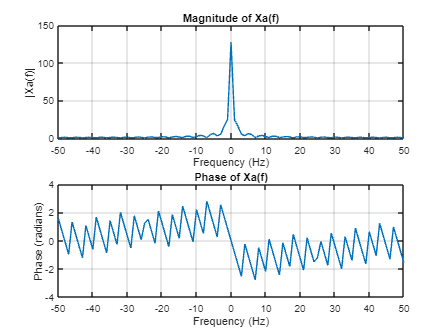

### C.now to use x(t) = cos(2*pi*50*t) + 2*cos(2*pi*100*t) to generate the following samples of x(t) using twosidedfft.m written in part a.

### c1.x500(n) with length 512, with a sampling of 500Hz.

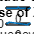

% Define your input signal x(n) and sampling frequency fs
fs = 500; % Example sampling frequency of 100Hz
N = 512;
t = 0:N-1; % Time vector from 0 to 1 second
x = 500 *(cos(2 * pi * 50 * t) + 2*cos(2*pi*100*t)); % Example input signal

% Define the frequencies at which to calculate the Fourier transform
freq = -50:1:50; % Example frequency vector from -50 Hz to 50 Hz

% Call the function to calculate the Fourier transform
Xa = twosidedfft(x, fs, freq);

% Plot the magnitude and phase of the Fourier transform
figure;
subplot(2,1,1);
plot(freq, abs(Xa));
title('Magnitude of Xa(f)');
xlabel('Frequency (Hz)'); ylabel('|Xa(f)|');
grid on;

subplot(2,1,2);
plot(freq, angle(Xa));
title('Phase of Xa(f)');
xlabel('Frequency (Hz)'); ylabel('Phase (radians)');
grid on;

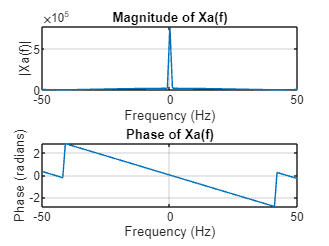

### c2.x250(n) with a length 256 and a sampling at 250Hz.

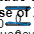

% Define your input signal x(n) and sampling frequency fs
fs = 250; % Example sampling frequency of 100Hz
N = 256;
t = 0:N-1; % Time vector from 0 to 1 second
x = 250 *(cos(2 * pi * 50 * t) + 2*cos(2*pi*100*t)); % Example input signal

% Define the frequencies at which to calculate the Fourier transform
freq = -50:1:50; % Example frequency vector from -50 Hz to 50 Hz

% Call the function to calculate the Fourier transform
Xa = twosidedfft(x, fs, freq);

% Plot the magnitude and phase of the Fourier transform
figure;
subplot(2,1,1);
plot(freq, abs(Xa));
title('Magnitude of Xa(f)');
xlabel('Frequency (Hz)'); ylabel('|Xa(f)|');
grid on;

subplot(2,1,2);
plot(freq, angle(Xa));
title('Phase of Xa(f)');
xlabel('Frequency (Hz)'); ylabel('Phase (radians)');
grid on;

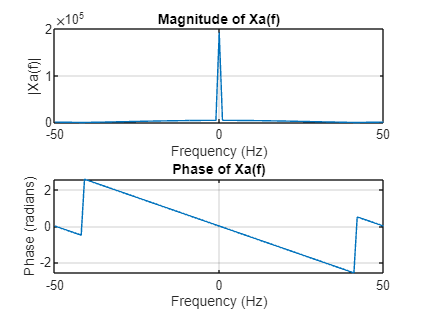

### c3.x125(n) with a sequence length 128 with sampling of 125Hz.

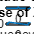

% Define your input signal x(n) and sampling frequency fs
fs = 125; % Example sampling frequency of 100Hz
N = 128;
t = 0:N-1; % Time vector from 0 to 1 second
x = 125 *(cos(2 * pi * 50 * t) + 2*cos(2*pi*100*t)); % Example input signal

% Define the frequencies at which to calculate the Fourier transform
freq = -50:1:50; % Example frequency vector from -50 Hz to 50 Hz

% Call the function to calculate the Fourier transform
Xa = twosidedfft(x, fs, freq);

% Plot the magnitude and phase of the Fourier transform
figure;
subplot(2,1,1);
plot(freq, abs(Xa));
title('Magnitude of Xa(f)');
xlabel('Frequency (Hz)'); ylabel('|Xa(f)|');
grid on;

subplot(2,1,2);
plot(freq, angle(Xa));
title('Phase of Xa(f)');
xlabel('Frequency (Hz)'); ylabel('Phase (radians)');
grid on;

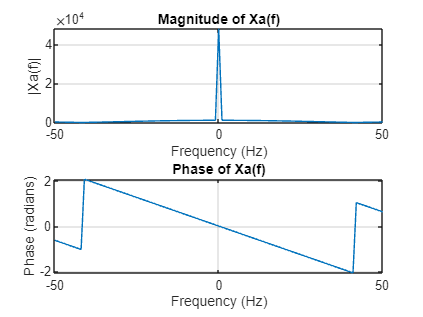

Now, these three three are compared with the potential help of the sampling theorem.